clc; clear;
warning off;

# Exercise 3.9

Derive the equations of motion using the Lagrange's method for the 3-link manipulator shown below, with the end-effector constrained to move along circular path.

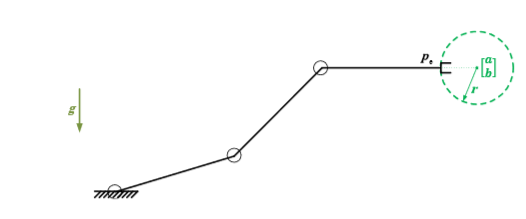

## Numerical values:

L1 = 1;
L2 = 1;
L3 = 1;
l1 = L1/2;
l2 = L2/2;
l3 = L3/2;
ml1 = 50;
ml2 = 50;
ml3 = 50;

Il1z = 10;
Il2z = 10;
Il3z = 10;
mm1 = 0;
mm2 = 0;
mm3 = 0;
Im1 = 0;
Im2 = 0;
Im3 = 0;

I1 = diag([0,0,Il1z]);
I2 = diag([0,0,Il2z]);
I3 = diag([0,0,Il3z]);

g = 9.8;
g0 = [0; -g; 0];

b_f = 10;

% constraint parameters
r = 0.5;
a = L1*cos(pi/3) + L2*cos(pi/4) + L3 + r;
b = L1*sin(pi/3) + L2*sin(pi/4);

% initial condition that satisfies the constraint
q10 = pi/3;
q20 = -(pi/3-pi/4);
q30 = -pi/4;
q0 = [q10; q20; q30];
q0dot = [0; 0; 0];

Ts = 1e-2;

## Symbolic variables:

syms lambda real; % Lagrange multiplier

q = sym('q',[3,1],'real');
dq = sym('dq',[3,1],'real');
ddq = sym('ddq',[3,1],'real');
tau = sym('tau',[3,1],'real');

## Transformation matrices:

A=@(a,al,d,th)([cos(th), -sin(th)*cos(al), sin(th)*sin(al), a*cos(th); sin(th), cos(th)*cos(al), -cos(th)*sin(al), a*sin(th); 0, sin(al), cos(al), d; 0, 0, 0, 1]);

A1_0 = A( L1,  0  , 0  , q(1) );
A2_1 = A( L2,  0  , 0  , q(2) );
A3_2 = A( L3,  0  , 0  , q(3) );

T1_0 = A1_0;
T2_0 = A1_0 * A2_1;
T3_0 = A1_0 * A2_1 * A3_2;

R1_0 = T1_0(1:3,1:3);
R2_0 = T2_0(1:3,1:3);
R3_0 = T3_0(1:3,1:3);

## Jacobian for each center of mass:

Z0 = [0;0;1];
Z1 = T1_0(1:3,3);
Z2 = T2_0(1:3,3);
Z3 = T3_0(1:3,3);

P0 = [0;0;0];
P1 = T1_0(1:3,4);
P2 = T2_0(1:3,4);
P3 = T3_0(1:3,4);

Pl1 = P0 + R1_0*[l1;0;0];
Pl2 = P1 + R2_0*[l2;0;0];
Pl3 = P2 + R3_0*[l3;0;0];

Jl1 = [cross(Z0,(Pl1-P0)),zeros(3,1),zeros(3,1);
       Z0,zeros(3,1),zeros(3,1)];

Jl2 = [cross(Z0,(Pl2-P0)),cross(Z1,(Pl2-P1)),zeros(3,1);
       Z0,Z1,zeros(3,1)];

Jl3 = [cross(Z0,(Pl3-P0)),cross(Z1,(Pl3-P1)),cross(Z2,(Pl3-P2));
       Z0,Z1,Z2];

## Kinetic and Potential Energy:

KineticEnergy = 1/2*dq.'*(Jl1(1:3,:).'*ml1* Jl1(1:3,:) + Jl2(1:3,:).' *ml2* Jl2(1:3,:) + Jl3(1:3,:).'*ml3* Jl3(1:3,:) + Jl1(4:6,:).'*R1_0*I1*R1_0.'*Jl1(4:6,:) + Jl2(4:6,:).'*R2_0*I2*R2_0.'*Jl2(4:6,:) + Jl3(4:6,:).'*R3_0*I3*R3_0.'*Jl3(4:6,:))*dq;

PotentialEnergy =  - ml1 * g0.' * Pl1 - ml2 * g0.' * Pl2  - ml3 * g0.' * Pl3;

## Constraint:

The manipulator is constrained to move along a circle:

$(x_{e}-a)^2 + (y_{e}-b)^2 = r^2$, where the end-effector position is described by: $P_e = \left[ x_e \ , y_e \ , \ 0 \right]^T$

The constraint can therefore be expressed with respect to the joint positions through direct kinematics:


$$ \phi(q_1 , q_2, q_3)   =  {\left(c_1 + c_{12} +c_{123}-a\right)}^2 +{\left(s_1 +s_{12} + s_{123} -b\right)}^2 - r^2$$


From this, we compute the constraint Jacobian:


$$J_\phi(q)
=
\left[\matrix{
\frac{\partial \phi}{\partial q_1} & 
 \frac{\partial \phi}{\partial q_2} & 
 \frac{\partial \phi}{\partial q_3}
}\right]
 =
2
\left[\begin{array}{ccc} 
a\,(s_{1} + s_{12} + s_{123})   -b\,(c_{1}+c_{12}+c_{123}) & 
a\,(s_{12} + s_{123})   -b\,(c_{12}+c_{123}) -(s_2+s_{23})& 
a\,s_{123}-b\,c_{123} -(s_{3}+s_{23}) 
\end{array}\right]$$


P_e = simplify(P3);
constraint = (P_e(1)-a)^2 + (P_e(2)-b)^2 - r^2;

dConstraint_q  = jacobian(constraint,q);
ddConstraint_q = jacobian(dConstraint_q*dq,q);

## Dynamic model with constraint:


$$B(q)\ddot{q} + C(q, \dot{q} )\dot{q} + g(q) + J_\phi^T (q)\lambda= \tau $$


% Lagrangian
Lagrangian = KineticEnergy - PotentialEnergy - lambda.'*constraint;
%simplify(Lagrangian)

dLag_dq  = jacobian(Lagrangian, dq).';
dLag_q   = jacobian(Lagrangian, q).';
ddLag_dq = jacobian(dLag_dq, dq);
ddLag_q  = jacobian(dLag_dq, q);

inertiaMatrix = ddLag_dq; % B
gVector = jacobian(PotentialEnergy,q).'; % g
coriolisMatrix = ddLag_q*dq - jacobian(KineticEnergy,q).'; % C
frictionOnJoints = -b_f*dq; % F

% Check if correct (should be zero):
simplify(dLag_q + dConstraint_q.'*lambda + gVector - jacobian(KineticEnergy,q).')

## Closed-form solution to Lagrange multipliers:


$$\left[ \matrix{ B(q)  & J_\phi^T(q) \cr
             J_\phi(q) & 0} \right]
\left[ \matrix{ \ddot{q} \cr 
\lambda } \right]
=
\left[ \matrix{\tau - n(q,\dot{q}) \cr
 -\dot{J}_\phi(q) \dot{q} }\right]$$


where $n (q,\dot{q}) = C(q,\dot{q})\dot{q}+g(q)$

modifiedInertiaMatrix = [inertiaMatrix dConstraint_q.';
                         dConstraint_q          0    ];

RHS_withoutConstraint = tau + frictionOnJoints - (coriolisMatrix + gVector);
%simplify(RHS_withoutConstraint)

RHS = [RHS_withoutConstraint;
      -ddConstraint_q*dq];
%simplify(RHS)

matlabFunction(modifiedInertiaMatrix,'File','modifiedInertiaMatrix','Vars',{q});
matlabFunction(RHS,'File','RHS','Vars',{q,dq,tau});

matlabFunction(inertiaMatrix,'File','inertiaMatrix','Vars',{q});
matlabFunction(RHS_withoutConstraint,'File','RHS_withoutConstraint','Vars',{q,dq,tau});

## Simulation without constraint:

sim('circle_sim_withoutConstraint')
pause(1);
visualization_3link

## Simulation with constraint:

clf;
sim('circle_sim')
pause(1);
visualization_3link